# Bridge of Doom

Anusha Karandikar and Benji Pugh 2021.

### Calculations

Initial Calculations:

% Using the Matlab Symbolic Toolbox to solve for properties of parametric curves
clc, clear all

% Define the symbolic variables we are using
syms u

% Define the parametric equation for the path or the bridge
ri=4*(0.3960*cos(2.65*(u+1.4)));
rj=4*(-0.99*sin(u+1.4));
rk=0*u;
r=[ri,rj,rk];

% Take the derivative of the parametric equation
dr=diff(r,u);

% Unit tangent vector
T_hat_ugly=dr./norm(dr);

% Simplify the algebra
assume(u,'real') % parameter u should be real

% Simplify the unit tangent vector
T_hat=simplify(T_hat_ugly);

% Unit normal vector
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat);

Encoder Data Calculations:

data = readtable('neatodata2.csv'); %,'PreserveVariableNames',true)


% From Encoder Data: Make all data relative to first value ("zero out" the data)
encoderRightmeters = data.encoderRight_meters_ - data.encoderRight_meters_(1);
encoderLeftmeters = data.encoderLeft_meters_ - data.encoderLeft_meters_(1);
timeseconds = data.time_seconds_ - data.time_seconds_(1);

% From Encoder Data: Trim beginning and end of data
encoderRightmeters = encoderRightmeters(76:200);    % position in meters
encoderLeftmeters = encoderLeftmeters(76:200);      % position in meters
timeseconds = timeseconds(76:200)-7.5;      % seconds; "zeroed out" values at timeseconds(76)

% Wheelbase
wheelbase = 0.235;      % meters

% For Calcuations
syms t
rt = subs(r, u, t/4);   % divide t by 4 to make max speed less than 2.0 meters/seconds
T_hat_t = diff(rt, t)/norm(diff(rt, t));
dTdt = diff(T_hat_t, t);

% For plotting
t_points = linspace(0,3.2*4, 100);  % multiply t by 4 since we divided by 4 in rt

% Calculated: Plotting unit tangent and unit normal vectors
u_points = linspace(0,3.2,4);
T_hat_values = subs(T_hat',u,u_points);
N_hat_values = subs(N_hat',u,u_points);
xy_points = subs(r',u,u_points);

% Calculated: Linear Speed
linear_speed = norm(diff(rt, t));                   % meters/seconds
% Points to plot
linear_speed_points = subs(linear_speed, t, t_points);

% Calculated: Angular Velocity
angular_velocity = cross(T_hat_t, dTdt);            % meters/seconds
% Points to plot
angular_velocity_points = subs(angular_velocity', t, t_points);

% From Encoder Data: Velocity of right and left wheels
velocity_R = diff(encoderRightmeters) ./ diff(timeseconds);     % meters/seconds
velocity_L = diff(encoderLeftmeters) ./ diff(timeseconds);      % meters/seconds

% From Encoder Data: Linear Speed
linear_experiment_speed = (velocity_L + velocity_R) / 2;        % meters/seconds

% From Encoder Data: Angular Velocity
angular_experiment_velocity = (velocity_R - velocity_L) / wheelbase;    % meters/seconds

% From Encoder Data: Left and Right Wheel Velocities
left_wheel_velocity = linear_speed - angular_velocity(:,3)*wheelbase/2;     % meters/seconds
right_wheel_velocity = linear_speed + angular_velocity(:,3)*wheelbase/2;    % meters/seconds
% Points to plot
left_velocity_points = subs(left_wheel_velocity',t,t_points);               % meters/seconds
right_velocity_points = subs(right_wheel_velocity',t,t_points);             % meters/seconds

% From Encoder Data: Reconstructing position of neato
starting_T_hat = double(subs(T_hat, u, 0));
starting_theta = atan(starting_T_hat(2)/starting_T_hat(1));     % radians
starting_position = double(subs(r(1:2), u, 0));                 % meters
theta_experimental = [starting_theta];
position_experimental = [starting_position];

for i = 1:length(angular_experiment_velocity)
    delta_t = diff(timeseconds);
    next_angle = theta_experimental(i) + (angular_experiment_velocity(i))*(delta_t(i));
    theta_experimental = [theta_experimental; next_angle];      % radians
end
for i = 1:length(linear_experiment_speed)
    delta_t = diff(timeseconds);
    experimental_T_hat = [cos(theta_experimental(i)), sin(theta_experimental(i))];
    change = linear_experiment_speed(i).*experimental_T_hat*delta_t(i);
    next_position = position_experimental(i,:) + change;
    position_experimental = [position_experimental; next_position];     % meters
end

### 21.1

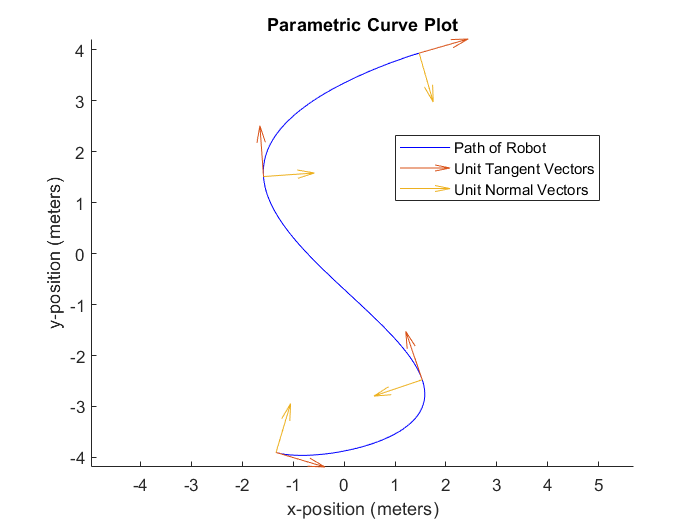

% Plotting the parametric curve
clf
hold on
axis equal
fplot(ri,rj,[0,3.2],'b-');
quiver(xy_points(1,:)',xy_points(2,:)',T_hat_values(1,:)',T_hat_values(2,:)', 0);
quiver(xy_points(1,:)',xy_points(2,:)',N_hat_values(1,:)',N_hat_values(2,:)', 0);
title("Parametric Curve Plot")
xlabel("x-position (meters)")
ylabel("y-position (meters)")
legend("Path of Robot","Unit Tangent Vectors","Unit Normal Vectors",'Location','best')
hold off

### 21.2

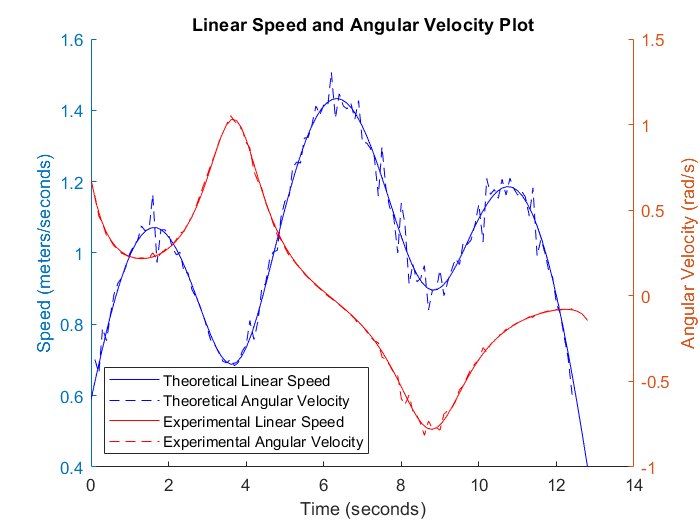

% Plotting the theoretical and experimental linear speed and angular velocity
clf
hold on
yyaxis left
plot(t_points,linear_speed_points,'b-')
ylabel("Speed (meters/seconds)")
yyaxis right
plot(t_points, angular_velocity_points(3,:)','r-')
ylabel("Angular Velocity (rad/s)")
yyaxis left
plot(timeseconds(2:end), linear_experiment_speed,'b--')
yyaxis right
plot(timeseconds(2:end), angular_experiment_velocity,'r--')
title("Linear Speed and Angular Velocity Plot")
legend("Theoretical Linear Speed","Theoretical Angular Velocity", ...
    "Experimental Linear Speed","Experimental Angular Velocity", 'Location','southwest')
xlabel("Time (seconds)")
hold off

### 21.3

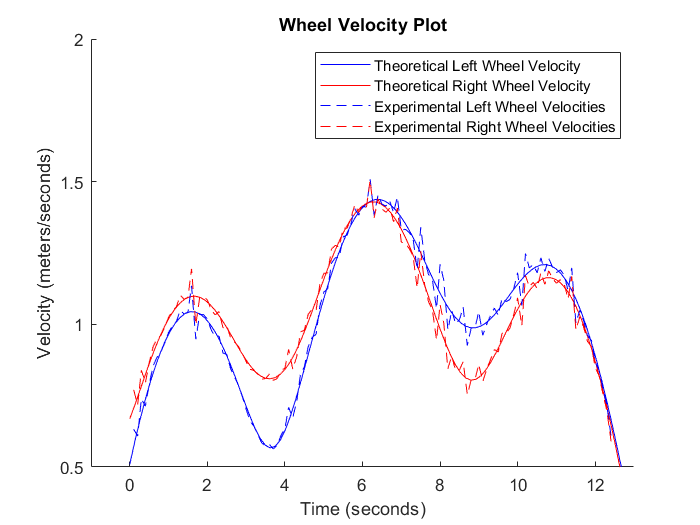

% Plotting the Theoretical and Experimental Wheel Velocities
clf
hold on
plot(t_points,left_velocity_points,'b-')
plot(t_points,right_velocity_points,'r-')
plot(timeseconds(2:end), velocity_L,'b--')
plot(timeseconds(2:end), velocity_R,'r--')
title("Wheel Velocity Plot")
legend('Theoretical Left Wheel Velocity','Theoretical Right Wheel Velocity', ...
    'Experimental Left Wheel Velocities','Experimental Right Wheel Velocities')
axis([-1 13 0.5 2])
xlabel("Time (seconds)")
ylabel("Velocity (meters/seconds)")
hold off

### 21.5

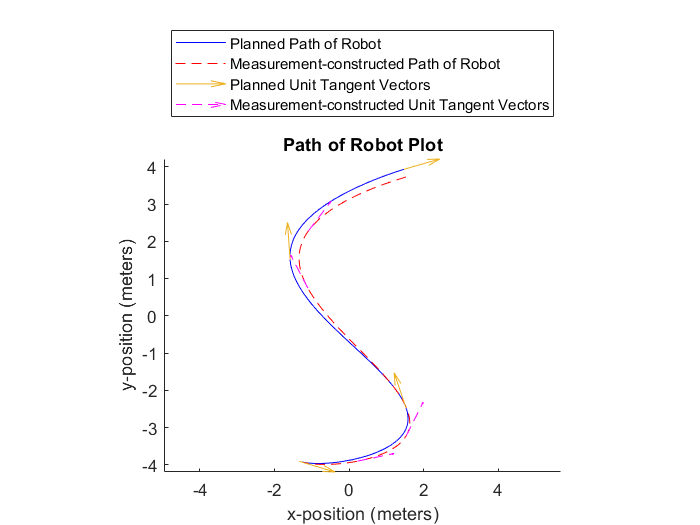

% Plotting the Theoretical and Experimental Robot Paths
clf
hold on
axis equal
fplot(ri,rj,[0,3.2],'b-');
plot(position_experimental(:,1), position_experimental(:,2),'r--')
quiver(xy_points(1,:)',xy_points(2,:)',T_hat_values(1,:)',T_hat_values(2,:)', 0);
% Selected 4 points to show the tangent vectors
quiver(position_experimental(18,1),position_experimental(18,2), cos(theta_experimental(18)), sin(theta_experimental(18)), 0, 'm--')
quiver(position_experimental(35,1),position_experimental(35,2), cos(theta_experimental(35)), sin(theta_experimental(35)),0, 'm--')
quiver(position_experimental(78,1),position_experimental(78,2), cos(theta_experimental(78)), sin(theta_experimental(78)),0, 'm--')
quiver(position_experimental(95,1),position_experimental(95,2), cos(theta_experimental(95)), sin(theta_experimental(95)),0, 'm--')
title("Path of Robot Plot")
xlabel("x-position (meters)")
ylabel("y-position (meters)")
legend("Planned Path of Robot","Measurement-constructed Path of Robot","Planned Unit Tangent Vectors", ...
    "Measurement-constructed Unit Tangent Vectors",'Location','northoutside')
hold off